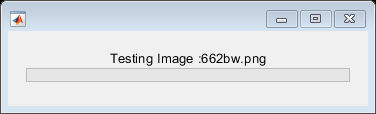

Error using DAGNetwork/calculatePredict>predictBatch (line 151)
Incorrect input size. The input images must have a size of [28 28 1].

Error in DAGNetwork/calculatePredict (line 17)
    Y = predictBatch( ...

Error in 

clear all;
path = "images/hard/";
[actual, predictions] = makePredictions(path, 0.1, 'Ratio');

[charAcc, numAcc] = calculateResults(actual, predictions);
character_accuracy = (charAcc/size(actual,2))*100;
word_accuracy = (numAcc/size(actual,2))*100;

function [img1, img2, img3, img4] = charSeparator_KMeans(img)
    mask = img>=120;
    [x,y] = find(mask==1);
    [idx,c] = kmeans(y,4);
    c = sort(c);
    m1 = round(c(1)/2);
    m2 = round((c(1)+c(2))/2);
    m3 = round((c(2)+c(3))/2);
    m4 = round((c(3)+c(4))/2);
    m5 = round((c(4)+size(img,2))/2);
    img1 = imresize(img(:,m1:m2),[28,28]);
    img2 = imresize(img(:,m2:m3),[28,28]);
    img3 = imresize(img(:,m3:m4),[28,28]);
    img4 = imresize(img(:,m4:m5),[28,28]);
end

function [img1, img2, img3, img4, img5] = charSeparator_Ratio(img)
    im_off = img(:,30:size(img,2));
    mask = (im_off >=120).*255;
    x = sum(255-mask);
    b = x>=800;
    im_cut = im_off(:,b);
    p = round(size(im_cut,2)/5);
    img1 = imresize(im_cut(:,1:p),[24,18]);
    img2 = imresize(im_cut(:,p:2*p),[24,18]);
    img3 = imresize(im_cut(:,2*p:3*p),[24,18]);
    img4 = imresize(im_cut(:,3*p:4*p),[24,18]);
    img5 = imresize(im_cut(:,4*p:size(im_cut,2)),[24,18]);
end


function [img1, img2, img3, img4] = charSeparator_LocalMinima(img)
    mask = (img >= 120);    
    y = sum(1-mask);
    lm = islocalmin(y);
    w = -9999*(lm-1);
    [v,i] = mink(y+w,3);
    i = sort(i);
    img1 = imresize(img(:,1:i(1)),[28,28]);
    img2 = imresize(img(:,i(1):i(2)),[28,28]);
    img3 = imresize(img(:,i(2):i(3)),[28,28]);
    img4 = imresize(img(:,i(3):size(img,2)),[28,28]);
end

function [result] = getCharacters(imgName, imgPath, charSepAlgo)
    load('CNN_net.mat', 'net')
    img = rgb2gray(imread(strcat(imgPath,imgName)));
    characters = {};
    ans = '';
    if strcmp(charSepAlgo, 'KMeans')
        [img1, img2, img3, img4] = charSeparator_KMeans(img);
    elseif strcmp(charSepAlgo, 'LocalMinima')
        [img1, img2, img3, img4] = charSeparator_LocalMinima(img);
    elseif strcmp(charSepAlgo, 'Ratio')
        [img1, img2, img3, img4, img5] = charSeparator_Ratio(img);
    end
    
    characters = [characters, img1];
    characters = [characters, img2];
    characters = [characters, img3];
    characters = [characters, img4];
    if strcmp(charSepAlgo, 'Ratio')
        characters = [characters, img5];
    end
    
    for k=1:size(characters, 2)
        folder = strcat('CNN_demo/',string(k));
        mkdir(folder);
        baseFileName = sprintf('%s.png', string(k));
        fullFileName = fullfile(folder, baseFileName);
        imwrite(characters{k}, fullFileName);
        imd = imageDatastore('CNN_demo/', ...
            'IncludeSubfolders',true);
        arr = cellstr(classify(net,imd));
        ans = strcat(ans,arr);
        rmdir('CNN_demo','s');
    end
    result = ans{1};
end

function [actual, predictions] = makePredictions(path, imagePerc, charSepAlgo)
    f = waitbar(0,'Please wait...');
    files_png = dir(fullfile(path,"*.png"));
    num_of_png_imgs = numel(files_png);
    predictions = {};
    actual = {};
    numImgs = round(num_of_png_imgs * imagePerc);
    rng(22);
    idx = randperm(num_of_png_imgs, numImgs);
    perct = 0;
    for i = 1:numImgs
        imgName = files_png(idx(i)).name;
        waitbar(perct,f,strcat('Testing Image :', imgName));
        [result] = getCharacters(imgName, path, charSepAlgo);
        str = strsplit(files_png(idx(i)).name, '.');
        actual = [actual, str{1}];
        predictions = [predictions, result];
        perct = perct + (1/numImgs);
    end
    close(f);
end

function [charAcc, numAcc] = calculateResults(actual, predictions)
    numAcc = 0;
    charAcc = 0;
    for i = 1:size(actual,2)
        char_acc = 0;
        if strcmp(actual(i),predictions(i)) == 1
            numAcc = numAcc + 1;
        end
        for j = 1:4
            actual_char = actual(i);
            pred_char = predictions(i);
            if strcmp(actual_char{1}(j),pred_char{1}(j)) == 1
                char_acc = char_acc + 1;
            end         
        end
        charAcc = charAcc + (char_acc / 4);
    end
end